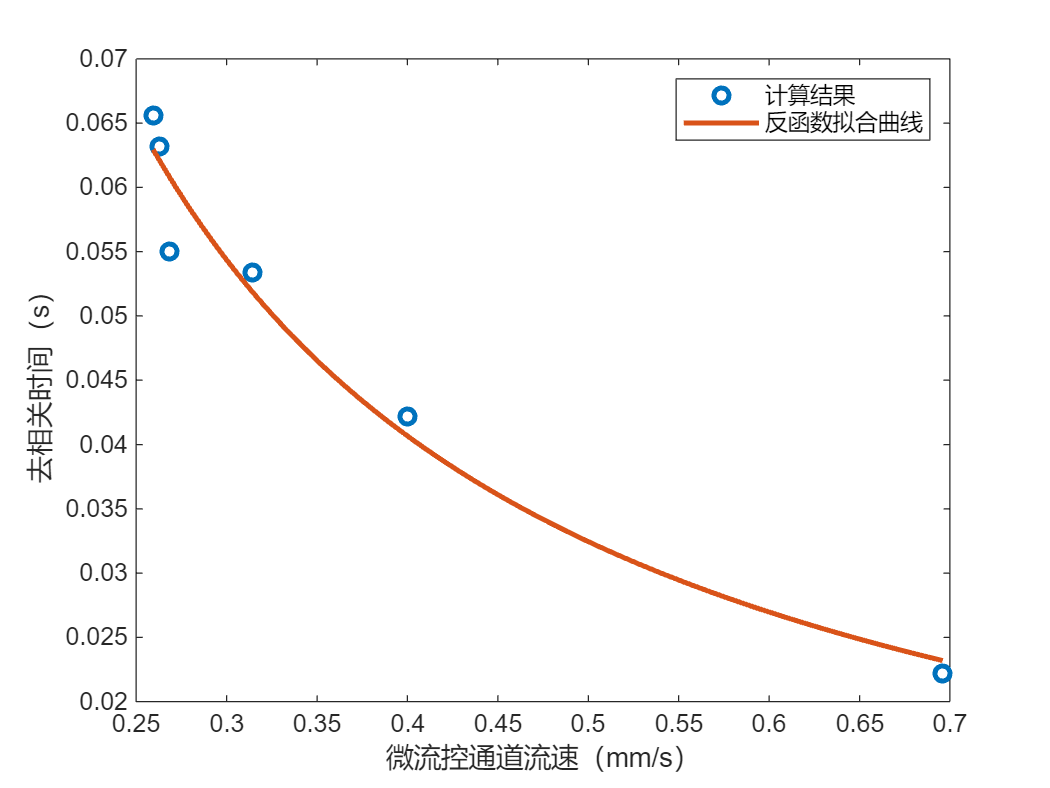

clc; clear;

% 定义速度理论值x, 速度实际值x1，去相关时间y

% 微流控实验，拍摄样本是离心提纯后的血液，在上面覆盖一层固态仿体（厚度0.8~1.0mm），筛选并提取单一像素点的数据
% x = [0.2778 0.5556 0.8333 1.1111 1.3888 1.6667 1.9444 2.2222]; % 速度的理论值
% x1 = [0.27534 0.57109 0.90364 1.1618 1.4688 1.7999 2.0716 2.1741]; % 速度的计算结果
% y = [0.0638 0.0307 0.01944 0.01512 0.01196 0.00976 0.00848 0.00808]; % 去相关时间

% 小鼠耳朵成像实验，筛选并提取单一像素点的数据
x = [0.695952 0.400072 0.314038 0.268224 0.263053 0.259326];
x1 = [0.70984 0.37342 0.2951 0.28652 0.24934 0.24022];
y = [0.0222 0.0422 0.0534 0.055 0.0632 0.0656];

% 第一幅图：半高宽随速度变化图
figure; % 创建第一个图形窗口
plot(x, y, 'o', 'LineWidth', 2); % 绘制半高宽随速度变化的原始数据
hold on;

% 对 x 取倒数
inv_x = 1 ./ x;

% 进行线性拟合
p = polyfit(inv_x, y, 1); % 一次多项式拟合倒数后的数据

% 计算拟合曲线的数据
inv_x_fit = linspace(min(inv_x), max(inv_x), 100);
y_fit = polyval(p, inv_x_fit);

% 绘制拟合曲线
plot(1 ./ inv_x_fit, y_fit, '-', 'LineWidth', 2); % 绘制拟合曲线
hold off;

% 添加标题、图例和标签
legend('计算结果', '反函数拟合曲线'); % 添加图例
xlabel('微流控通道流速（mm/s）'); % x轴标签
ylabel('去相关时间（s）'); % y轴标签

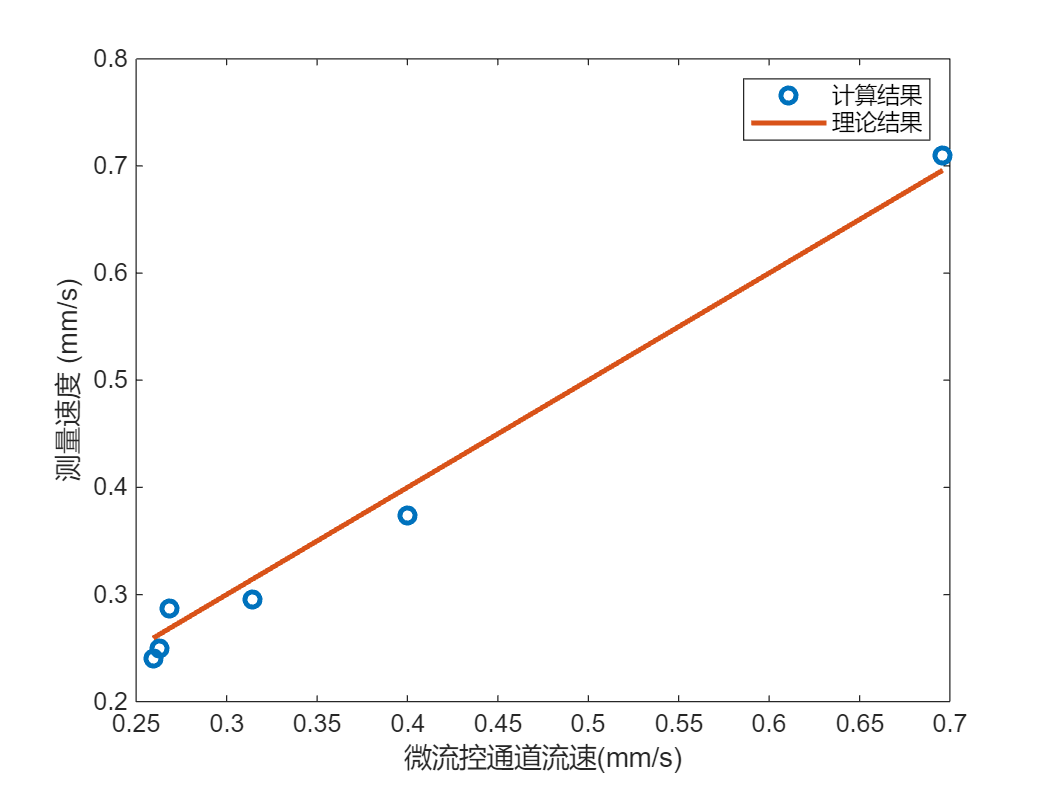


% 第二幅图：理论值与计算结果对比图
figure; % 创建第二个图形窗口
plot(x, x1, 'o', 'LineWidth', 2, 'DisplayName', '计算结果'); % 绘制计算结果
hold on;
plot(x, x, '-', 'LineWidth', 2, 'DisplayName', '理论结果'); % 绘制理论结果
hold off;

% 添加标题、图例和标签
legend('计算结果', '理论结果'); % 添加图例
xlabel('微流控通道流速(mm/s)'); % x轴标签
ylabel('测量速度 (mm/s)'); % y轴标签


% 计算速度平均误差
errors = abs(x - x1); % 计算绝对误差
mean_error = mean(errors); % 计算平均绝对误差
relative_errors = abs((x - x1) ./ x) * 100; % 计算相对误差（百分比）
mean_relative_error = mean(relative_errors); % 计算平均相对误差

% 输出结果
disp(['速度平均绝对误差：', num2str(mean_error), ' mm/s']);

速度平均绝对误差：0.018432 mm/s


disp(['速度平均相对误差：', num2str(mean_relative_error), '%']);

速度平均相对误差：5.6816%
